# Reto quanser qube

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



k=22.4

k = 22.4000

tau=0.15

tau = 0.1500


%dinamica de planta en continuo
gps=k/(s*(tau*s+1))


gps =
 
      22.4
  ------------
  0.15 s^2 + s
 
Continuous-time transfer function.




% 0.2 Tao equivalente
Tm=0.03;%tiempo de muestreo propuesto en la guia
gpz=c2d(gps,Tm,'zoh')


gpz =
 
   0.06294 z + 0.05888
  ----------------------
  z^2 - 1.819 z + 0.8187
 
Sample time: 0.03 seconds
Discrete-time transfer function.



%dinamica de planta en discreto
zpk(gpz)


ans =
 
  0.062935 (z+0.9355)
  -------------------
   (z-1) (z-0.8187)
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.



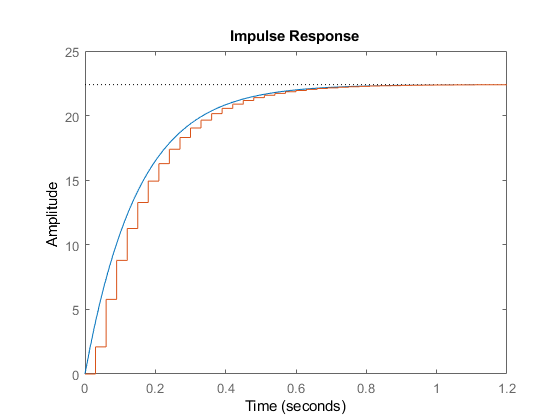


impulse(gps,gpz)

%dead-beat a un paso
C=tf(1,[1 -1],Tm) %integrador


C =
 
    1
  -----
  z - 1
 
Sample time: 0.03 seconds
Discrete-time transfer function.



Cc=1/gpz  % anular planta


Cc =
 
  z^2 - 1.819 z + 0.8187
  ----------------------
   0.06294 z + 0.05888
 
Sample time: 0.03 seconds
Discrete-time transfer function.



Gc1p=C*Cc  % construccion del controlador


Gc1p =
 
        z^2 - 1.819 z + 0.8187
  ----------------------------------
  0.06294 z^2 - 0.004058 z - 0.05888
 
Sample time: 0.03 seconds
Discrete-time transfer function.



Ldirect=Gc1p*gpz  %lazo directo


Ldirect =
 
                                                
  0.06294 z^3 - 0.05558 z^2 - 0.05556 z + 0.0482
                                                
  ----------------------------------------------
                                                
  0.06294 z^4 - 0.1185 z^3 + 2.94e-05 z^2       
                                                
                             + 0.1038 z - 0.0482
                                                
 
Sample time: 0.03 seconds
Discrete-time transfer function.



Sys1=feedback(Ldirect,1) %lazo cerrado


Sys1 =
 
                                                
  0.06294 z^3 - 0.05558 z^2 - 0.05556 z + 0.0482
                                                
  ----------------------------------------------
                                                
  0.06294 z^4 - 0.05558 z^3 - 0.05556 z^2       
                                                
                                      + 0.0482 z
                                                
 
Sample time: 0.03 seconds
Discrete-time transfer function.



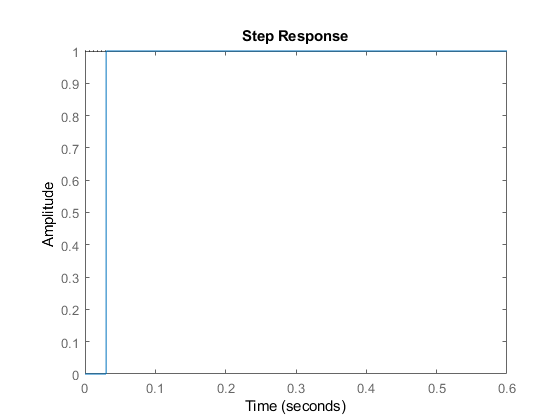

step(Sys1) % respuesta al escalon

%dead-beat normal
q0=1/sum(gpz.num{1}); %constante q0
z=tf('z',Tm)


z =
 
  z
 
Sample time: 0.03 seconds
Discrete-time transfer function.



% Gcdbn=tf(q0*gpz.den{1},[1 -q0*gpz.num{1}],Tm) %construccion controlador
Gcdbn=tf(q0*gpz.den{1},[1 -q0*gpz.num{1}],Tm) %construccion controlador


Gcdbn =
 
  8.209 z^2 - 14.93 z + 6.721
  ---------------------------
    z^3 - 0.5167 z - 0.4833
 
Sample time: 0.03 seconds
Discrete-time transfer function.



Sys2=feedback(Gcdbn*gpz,1)  %lazo cerrado


Sys2 =
 
  0.5167 z^3 - 0.4563 z^2 - 0.4561 z + 0.3957
  -------------------------------------------
  z^5 - 1.819 z^4 + 0.8187 z^3 + 5.551e-17 z
 
Sample time: 0.03 seconds
Discrete-time transfer function.



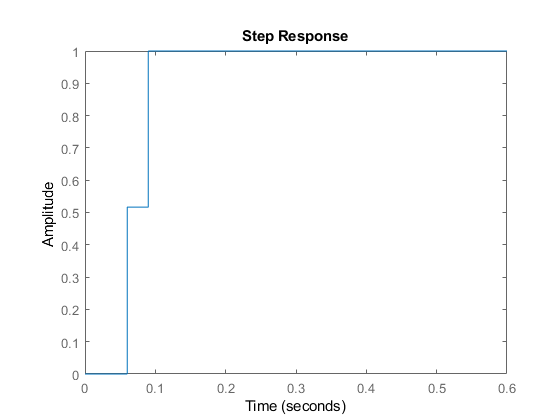

step(Sys2)  %respuesta al escalon

%controlador PV diseñado en continuo
mp=0.05

mp = 0.0500

tp=0.2

tp = 0.2000

x=log(mp)

x = -2.9957

zita=1/(sqrt((pi^2/(x^2))+1))

zita = 0.6901

wn=pi/(tp*sqrt(1-(zita^2)))

wn = 21.7048


% polinomio deseado en continuo
Bd_c=s^2+2*zita*wn*s+wn^2;
Bdeseado_c=1/Bd_c;
Bdeseado_c=Bdeseado_c/dcgain(Bdeseado_c);

% polinomio deseado en discreto
M=exp(-zita*wn*Tm)

M = 0.6380

phi=wn*sqrt(1-zita^2)*Tm

phi = 0.4712

Bd_d=z^2-2*M*cos(phi)*z+M^2


Bd_d =
 
  z^2 - 1.137 z + 0.4071
 
Sample time: 0.03 seconds
Discrete-time transfer function.



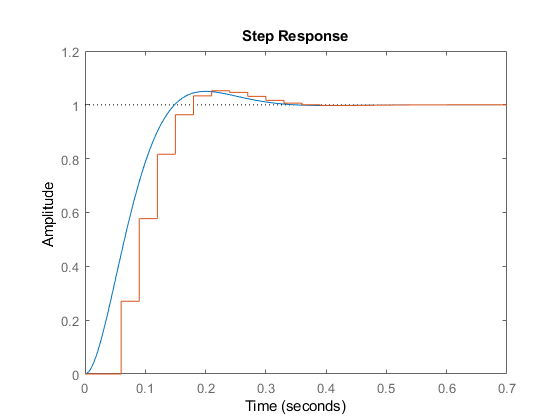

Bdeseado_d=1/Bd_d;
Bdeseado_d=Bdeseado_d/dcgain(Bdeseado_d);
step(Bdeseado_c,Bdeseado_d)


kp = 3.154676404, kv = -0.1559618189

kp = 3.1547

kv = -0.1560

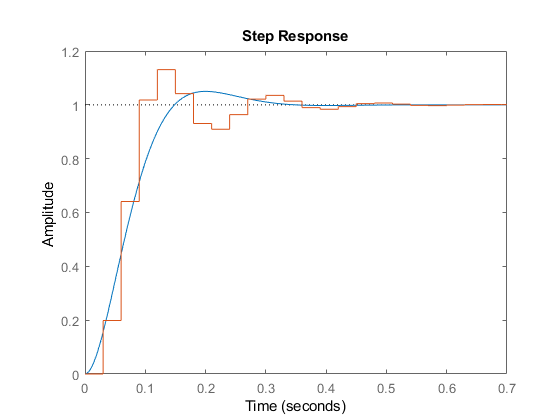


C1=kv*(z-1)/(z*Tm);
C2=kp;

lazoEsclavo_cerrado=feedback(gpz,-C1);
lazoMaestro_cerrado=feedback(C2*lazoEsclavo_cerrado,1);

step(Bdeseado_c)
hold on
step(lazoMaestro_cerrado)
hold off


% Nota: parece que la grafica no se parece
% es por que la derivada es una aproximacion de mas
% solo es necesaria para modelar, pero en simulink
% se ve que con una derivada analitica en continuo
% pinta bien